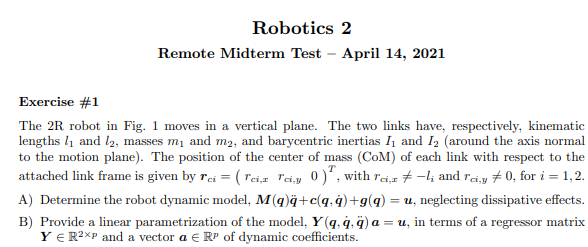

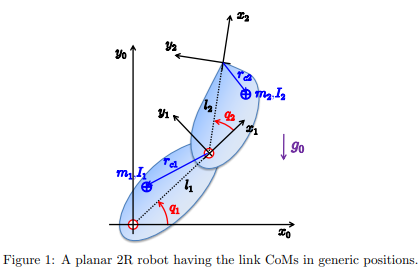

% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% % alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% 
% 

% R2Robot=['rr';'xx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% % l(1)=0 %don't do this because dc1 is going to dissaperar
% % z.opt_expr={[l(1)],[0]};%use this instead
% % z.opt_expr={[m(1)],[0]};%use this instead
% % z.opt_expr={dc(1),[r_c_1]};%use this instead
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% 
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% 
% % z.rcdefined=true;
% % z.prismatic_CoM_method(2)=2;
% z.xyonly=true
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% r_c_1_x=sym('r_c_x_',[n,1],'real');
% r_c_1_y=sym('r_c_y_',[n,1],'real');
% r_c_1_z=sym('r_c_z_',[n,1],'real');
% 
% z.dc=[r_c_1_x,r_c_1_y,r_c_1_z]';
% %defiing dc method
% z.dc_method=1
% z.dc

% % % % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% % % %             0       , z.l(2)  , 0   , q(2);]

% % % % 
% % % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

% Ti(1)
% Pc
% M
% % 

% % R_=[cos(z.q(1)+z.q(2)),-sin(z.q(1)+z.q(2));sin(z.q(1)+z.q(2)),cos(z.q(1)+z.q(2))]
% % pc_part_=((R_*[z.l(2)+r_c_2_x;r_c_2_y]))

## Potential energy definition

% % %special potential energy
% % k=sym('k','real')
% % f_u=[(k*z.q(1).^2)/2,0]'

% isMotor=false
% % 
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)
% % [grad_f,PE, U,grad_f_short,PE_short] = getGradient(f_u,z.q)%,gradient computation

% U{:}
% g_q

% [C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)
% % 

% % C{1}
% % cac
% % S

% [All, dynamicParamsReturn, aM]= getDynamicParameters2([M,diag(g_q),S],q,[z.q_dot],1);
% % [All, dynamicParamsReturn, aM]= getDynamicParameters2([M],q,[z.q_dot],1)

% 
% Msubs = All(:,1:n)
% gsubs = diag(All(:,n+1:2*n))
% Ssubs = All(:,2*n+1:3*n)
% aM
% dynamicParamsReturn

% 
% torqueSubs = Msubs*z.q_ddot + Ssubs*z.q_dot + gsubs% +FSubs*qd

% a_order=aM([3,5,8,1,2,6,4,7])
% [Y, Yshort]=getLinearParametrization(torqueSubs,a_order)

## Exercise 4

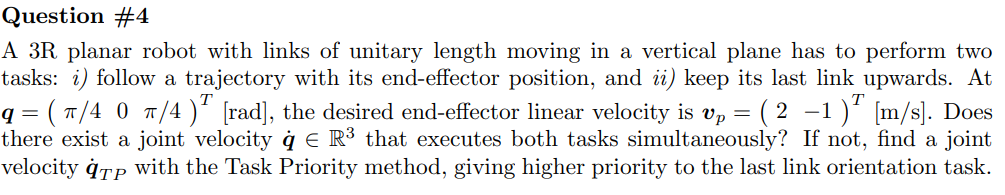

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0,0];
% R2Robot=['rrr';'xxx';sigma]
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym("l","real");
% l_0_=1%sym('l','real')
% % h=sym('h','real');
% % h_=1;
% z.opt_expr={[l],[l_0_,l_0_,l_0_]'};%not necessary
% 
% % z.rcdefined=true;

## axis offset

% % 
% % 
% % %x,y,z
% % % z.xyx_offset=sym(zeros(3,n));
% % % z.xyx_offset(:,1)=[0,h,0]';%

% % %Global q reference?
% % % clear
% % % z.q_global
% % z.global_q_reference=true;
% % if(z.global_q_reference)
% %     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
% % end
% 

Defining task order

% pd={sym('pd_1_',[1,1],'real'),sym('pd_2_',[2,1],'real')};
% pd_dot={sym('pd_dot_1_',[1,1],'real'),sym('pd_dot_2_',[2,1],'real')};
% 
% % px_0=sym('P_x_0','real');
% % z.task_defined={struct('f',[px_0;l_0*(sin(z.q(1))+sin(z.q(2))+sin(z.q(3)))],'pd_',pd{2}),struct('f',q(2),'pd_',pd{1})} ;%pc is note necessary
% 
% % z.task_defined={struct('f','end_effector','pd_',pd{2},'pd_dot_',[0.1,-0.5]'),struct('f',sum([q(1),q(2),0]),'pd_',pd{1},'pd_dot_',[0])} %pc is note necessary
% 
% z.task_defined={struct('f',sum(q),'pd_',pi/2,'pd_dot_',[0]),struct('f','end_effector','pd_',pd{2},'pd_dot_',[2,-1]')} ;%pc is note necessary
% 
% %
% z.task_defined

% % % xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z);
% % % VarShortRobot.M
% % % angle_desired=[0,0]
% % % l(1)=0
% % % [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

% f
% J
% % % M
% % % Pc
% % % simplify((Ti'))
% % % vc
% % % simplify(Trans.PTotal)
% % % Trans.PPartial{:}
% % J
% 

## Checking if it is possible solve the both task ath teh same time

% q_=[pi/4,0,pi/4]';
% v=[0;2;-1]
% to_replace=[l_0;z.q]
% l_0_=1
% to_replace_=[l_0_;q_]
% % P_0_=subs(f(1:2),to_replace,to_replace_)
% J_A_0_=subs(J,q,q_)
% 
% q_dot_0_ps_=vpa(pinv(J_A_0_)*v)%%succesfully done
% error_ps=vpa(v-J_A_0_*q_dot_0_ps_)

% q_=[pi/4,0,pi/4]';
% to_replace=[l_0;z.q]
% l_0_=1
% to_replace_=[l_0_;q_]
% P_0_=subs(f(1:2),to_replace,to_replace_)
% 
% % qs1=vpa(acos((P_0_(1)-1)/2));
% % 
% % qs_=[qs1,0,qs1]'
% % 
% % to_replace=[l_0;z.q]
% % to_replace_=[1;qs_]
% % P_0_s_=subs(f(3),to_replace,to_replace_)
% % 

## rank of J

% rank(J)
% J(:,1:end)
% simplify(det(J(:,1:end)))

% rd_1=f(1:1,:)
% rd_2=f(2:end,:)
% % 
% % 
% % 

## redundancy task with prioriy

% replace_values=true
% % vars2replace=[z.q;z_q_dot_k,z.]
% z.q_=[pi/4,0,pi/4]';
% % q_s1=[0.5480; 0; 0.548];
% 
% [q_dot_k,z_task] = Redundancy_tasks_with_Priority(z,PC_EE,replace_values);

% % q_dot_k{:};
% % z_task.J_k{:};
% % z_task.J_k_pinv{:};
% % z_task.P_A_k{:};
% % 
% z_task.q_dot_k_{:}
% z_task.J_k_{:}
% z_task.J_k_pinv_{:}
% z_task.P_A_k_{:}

J_A_0 evaluation with pririty task

% J_A_0_=subs(J,q,q_)
% z_task.q_dot_k_{2}
% error_pt=vpa(v-J_A_0_*z_task.q_dot_k_{2})

**J_A_s evaluation**

**Pseudoinversion**

% % % P_0=subs(z_path.rd,z_path.theta,pi/2)%[10,0]';
% % vpa(P_0)
% % rd_dot_s_=z_path.rd_dot_; %v=1
% % q_s_=q_sol2_
% % J_A_s_=subs(J,q,q_s_)
% % pinv(J_A_s_)
% % q_dot_s_=pinv(J_A_s_)*[rd_dot_s_;0]%%succesfully done

**J_A_s evaluation**

**Damped Least Squares**

% % % P_0=subs(z_path.rd,z_path.theta,pi/2)%[10,0]';
% % vpa(P_0)
% % rd_dot_s_=z_path.rd_dot_; %v=1
% % q_s_=q_sol2_
% % J_A_s_=round(subs(J,q,q_s_),4)
% % 
% % pinv(J_A_s_)
% % miu=sqrt(0.25)
% % J_A_s_damp_=Inverse_Damped_Jacobian(J_A_s_,miu)
% % q_dot_damp_s_=J_A_s_damp_*[rd_dot_s_;0]%%succesfully done

## Task Priority

## redundancy task with prioriy

% % replace_values=true
% % % vars2replace=[z.q;z_q_dot_k,z.]
% % z.q_=[0.5480; 0; 0.548]
% % % q_s1=[0.5480; 0; 0.548];
% % PC_EE.pd_dot_{1}=[0,1]';
% % PC_EE.pd_dot_{2}=0;
% % [q_dot_k,z_task] = Redundancy_tasks_with_Priority(z,PC_EE,replace_values);

% % z_task.q_dot_k_{2}

## tessting solutions

% % rd_dot_s2_=J_A_s_*q_dot_s_%% succesfully completed!!!
% % 
% % rd_dot_s2_=J_A_s_*q_dot_damp_s_%% succesfully completed!!!
% % 
% % rd_dot_s2_=J_A_s_*z_task.q_dot_k_{2}%% succesfully completed!!!


## Exercise 9

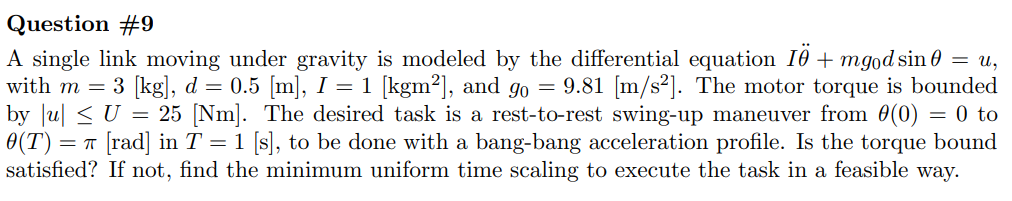


% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [1];
R2Robot=['r';'y';sigmaD]

R2Robot = 3×1 char array
    'r'
    'y'
    ''


n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
g0 = sym('g0','real');
g=[0,g0,0]';

z = Gen_param(n);
z.sigmaD=R2Robot;
% l(1)=0 %don't do this because dc1 is going to dissaperar
% z.opt_expr={[l(1)],[0]};%use this instead
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.q_ddot=q_ddot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table, 1 normal mode

z = struct with fields:
                  sigmaD: [3×1 char]
                       l: [1×1 sym]
                      l_: []
                       q: [1×1 sym]
                   q_dot: [1×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [1×1 sym]
                       m: [1×1 sym]
                       I: [1×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 1
                  angle_: [1×1 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: 1
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
           

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));

% z.rcdefined=true;
% z.prismatic_CoM_method(2)=2; %apy attention to this
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×1 char]
                       l: [1×1 sym]
                      l_: []
                       q: [1×1 sym]
                   q_dot: [1×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [1×1 sym]
                       m: [1×1 sym]
                       I: [1×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 1
                  angle_: [1×1 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: 1
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
           

% q = sym('q', [n,1],'real');
% qd= sym('qd', [n,1],'real');
% a = sym('a', [n,1],'real');
% d = sym('d', [n,1],'real');

% % % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% % %             0       , z.l(2)  , 0   , q(2);]

% % % 
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
[Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×1 char]
                       l: [1×1 sym]
                      l_: []
                       q: [1×1 sym]
                   q_dot: [1×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [1×1 sym]
                       m: [1×1 sym]
                       I: [1×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 1
                  angle_: [1×1 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: 1
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
           

si falla aquí está el error


$$a = l_{1}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

$$To\_derive = \left(\begin{array}{c} -l_{1}\,\cos\left(q_{1}\left(t\right)\right)\\ -l_{1}\,\sin\left(q_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

$$q\_t = q_{1}\left(t\right)$$

z_derivated = struct with fields:
    dot_t: [3×1 sym]


z_derivated = struct with fields:
     dot_t: [3×1 sym]
    ddot_t: [3×1 sym]


z_derivated = struct with fields:
     dot_t: [3×1 sym]
    ddot_t: [3×1 sym]
    tdot_t: [3×1 sym]


z_derivated = struct with fields:
        dot_t: [3×1 sym]
       ddot_t: [3×1 sym]
       tdot_t: [3×1 sym]
          dot: [3×1 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×1 sym]
       ddot_t: [3×1 sym]
       tdot_t: [3×1 sym]
          dot: [3×1 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []
          tdot: [3×1 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []
          tdot: [3×1 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{c} -{\mathrm{dc}}_{1}\,\sin\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

$$vc = \left(\begin{array}{c} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\\ -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

$$w = \left(\begin{array}{c} 0\\ 0\\ {\dot{q}}_{1} \end{array}\right)$$

$$T = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

$$M = m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}$$

VarShortRobot = struct with fields:
    Pc: [3×1 sym]
    vc: [3×1 sym]
     w: [3×1 sym]
     T: [1×1 sym]
    Ti: [1×1 sym]
     M: [1×1 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×1 sym]
               TPartial: {[4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×1 sym]
    Jacobian_dot_PTotal: [3×1 sym]
               PPartial: {[3×1 sym]}
                     Pc: [3×1 sym]
                RTotali: {[3×3 sym]}
           ThetaPartial: [1×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×1 sym]
                      w: [3×1 sym]
                      T: [1×1 sym]
                     Ti: [1×1 sym]
                      M: [1×1 sym]


% Ti(1)
% T
% Pc

M

$$M = m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}$$

Pc

$$Pc = \left(\begin{array}{c} -{\mathrm{dc}}_{1}\,\sin\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

[C,cac,Csubs,S] = getCs(M,z.q,z.q_dot);

>> Getting  the Christoffel’sym. Might take a while...


S

$$S = 0$$

isMotor=false

isMotor = logical
   0


% 
[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cc} \sin\left(q_{1}\right) & \cos\left(q_{1}\right) \end{array}\right)$$

$$PE = -{\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)$$

$$PE\_short = -{\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)$$

$$g\_q\_short = {\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

$$g\_q = {\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

$$PE = -{\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)$$

U = 1×1 cell array
    {1×1 sym}


$$g\_q\_short = {\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

$$PE\_short = -{\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)$$

g_q

$$g\_q = {\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

[All, dynamicParamsReturn, aM]= getDynamicParameters2([M,g_q],q,[z.q_dot],1)

$$none\_sym\_value = {\mathrm{zxw}}_{\mathrm{none},\mathrm{David}}$$

>> Getting dynamic coefficients. Might take a while...
MSubs second iteration (before re-replacement)
si falla uncomment this line verify  una lineas arriba


$$All = \left(\begin{array}{cc} a_{1} & a_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

$$dynamicParamsReturn = \left(\begin{array}{c} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\\ {\mathrm{dc}}_{1}\,g_{0}\,m_{1} \end{array}\right)$$

$$aM = \left(\begin{array}{c} a_{1}\\ a_{2} \end{array}\right)$$

% 
Msubs = All(:,1:n)

$$Msubs = a_{1}$$

gsubs = diag(All(:,n+1:2*n))

$$gsubs = a_{2}\,\sin\left(q_{1}\right)$$

% Ssubs = All(:,2*n+1:3*n)
% aM
% dynamicParamsReturn

## MODEL

u=Msubs*z.q_ddot+S*z.q_dot+gsubs

$$u = a_{1}\,{\ddot{q}}_{1}+a_{2}\,\sin\left(q_{1}\right)$$

## Bang Cost Bang

m_=3

m_ = 3

g0_=9.81

g0_ = 9.8100

d0_=0.5

d0_ = 0.5000

a2_=m_*g0_*d0_

a2_ = 14.7150

I_=a2_

I_ = 14.7150


a1_=1

a1_ = 1

% theta_T=pi;
% theta_s_=theta_T/6
% I_=m_*l_^2/12+m_*(l_/2)^2
% g_0=9.81
% d_=l_/2
% tau_g_max_=m_*g_0*d_
% tau_max_=200
% sin(theta_s_)
% T_min=sqrt(16*I_*pi/(3*(tau_max_-tau_g_max_*sin(theta_s_))))


## bang cost bang profile

T=sym('T','real');
V1=sym('V1','real');
A1=sym('A_max','real');
alpha=sym('alpha','real');
% T_=1*T_min%1.2165;
T_=1;
% Ts_=T_/4
% alpha_=pi/6
U2_max=25

U2_max = 25

% U1_max=14%2*alpha_*m_*d_/I_*U2_max
% A2_=U2_max/I_

% Ts=T/4;
% V1=Ts*A1;
% V1_=Ts_*A1_;

qA=[0]'

qA = 0

qB_=[pi]'

qB_ = 3.1416

qB=sym('qB',[2,1],'real');
A2_=abs(qB_-qA)*4/T_^2

A2_ = 12.5664

theta_max=A2_*T_^2/8

theta_max = 1.5708

% I_0=1
% [qa_piece2,T_,Ts_,t] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
% [qa_piece2,T_,Ts_,t] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
[qa_piece2,Tres_,V_,qa_piece_sym] = BangBangPRofile(qA(1,1),qB_(1,1), A2_,T_)

$$qa\_piece = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ A_{1}\,\left(\frac{T}{2}-t\right)+\frac{A_{1}\,T}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ \frac{A_{1}\,T^{2}}{8}-\frac{A_{1}\,{\left(\frac{T}{2}-t\right)}^{2}}{2}-\frac{A_{1}\,T\,\left(\frac{T}{2}-t\right)}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right. \end{array}\right)$$

$$qa\_piece2 = \left(\begin{array}{c} \left\{ \begin{array}{cl} 12.566370614359172953850573533118 & \text{ if }t\in \left[0.0,0.5\right)\\ -12.566370614359172953850573533118 & \text{ if }t\in \left[0.5,1.0\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 12.566370614359172953850573533118\,t & \text{ if }t\in \left[0.0,0.5\right)\\ 12.566370614359172953850573533118-12.566370614359172953850573533118\,t & \text{ if }t\in \left[0.5,1.0\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 6.283185307179586476925286766559\,t^{2} & \text{ if }t\in \left[0.0,0.5\right)\\ 6.283185307179586476925286766559\,t-6.283185307179586476925286766559\,{\left(t-0.5\right)}^{2}-1.5707963267948966192313216916398 & \text{ if }t\in \left[0.5,1.0\right) \end{array}\right. \end{array}\right)$$

Tres_ = 1

V_ = 6.2832

$$qa\_piece\_sym = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ A_{1}\,\left(\frac{T}{2}-t\right)+\frac{A_{1}\,T}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ \frac{A_{1}\,T^{2}}{8}-\frac{A_{1}\,{\left(\frac{T}{2}-t\right)}^{2}}{2}-\frac{A_{1}\,T\,\left(\frac{T}{2}-t\right)}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right. \end{array}\right)$$

T_=Tres_

T_ = 1

simplify(qa_piece_sym)

$$ans = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ A_{1}\,\left(T-t\right) & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -\frac{A_{1}\,\left(T^{2}-4\,T\,t+2\,t^{2}\right)}{4} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right. \end{array}\right)$$

round(simplify(qa_piece2),3)

$$ans = \left(\begin{array}{c} \left\{ \begin{array}{cl} 12.566 & \text{ if }t\in \left[0.0,0.5\right)\\ -12.566 & \text{ if }t\in \left[0.5,1.0\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 0.001\,\mathrm{round}\left(12566.370614359172953850573533118\,t\right) & \text{ if }t\in \left[0.0,0.5\right)\\ 0.001\,\mathrm{round}\left(12566.370614359172953850573533118-12566.370614359172953850573533118\,t\right) & \text{ if }t\in \left[0.5,1.0\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 0.001\,\mathrm{round}\left(6283.185307179586476925286766559\,t^{2}\right) & \text{ if }t\in \left[0.0,0.5\right)\\ 0.001\,\mathrm{round}\left(-6283.185307179586476925286766559\,t^{2}+12566.370614359172953850573533118\,t-3141.5926535897932384626433832795\right) & \text{ if }t\in \left[0.5,1.0\right) \end{array}\right. \end{array}\right)$$

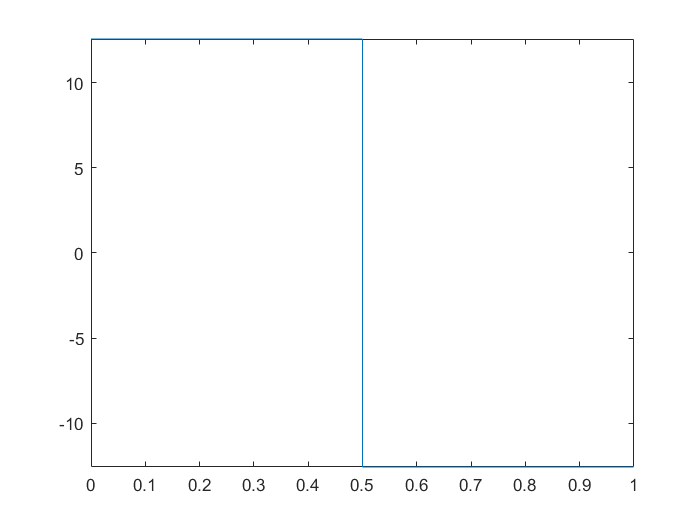


fplot(qa_piece2(1,:),[0,T_])

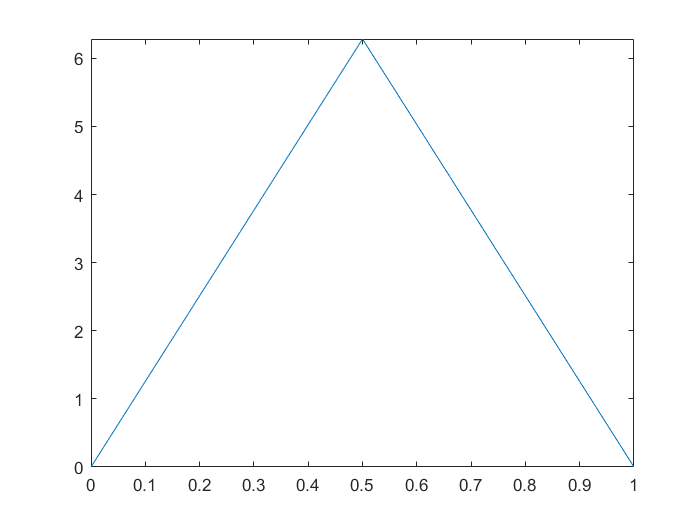

figure
fplot(qa_piece2(2,:),[0,T_])

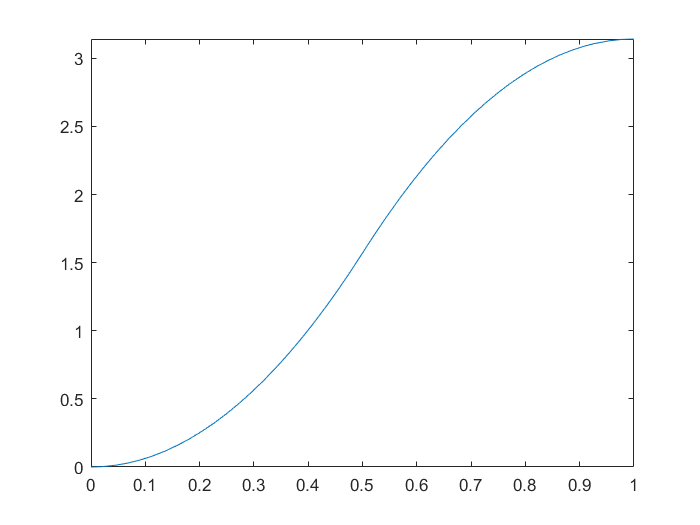

figure
fplot(qa_piece2(3,:),[0,T_])

figure
% [qa_piece2,T_,Ts_] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
% tau_2=int(qa_piece2,t)

## torques

u_=subs(u,[aM],[a1_;a2_])

$$u\_ = {\ddot{q}}_{1}+\frac{2943\,\sin\left(q_{1}\right)}{200}$$

g_max_=vpa(subs(u_,[z.q;q_ddot],[pi/2;0]))

$$g\_max\_ = 14.715$$

u_max_=vpa(subs(u_,[z.q;q_ddot],[theta_max;A2_]))

$$u\_max\_ = 27.281370614359172953850573533118$$

t=sym('t','real')

$$t = t$$

u1=subs(u_,[z.q;q_ddot],[qa_piece2(3,:);qa_piece2(1,:)])

$$u1 = \left\{ \begin{array}{cl} \frac{2943\,\sin\left(6.283185307179586476925286766559\,t^{2}\right)}{200}+12.566370614359172953850573533118 & \text{ if }t\in \left[0.0,0.5\right)\\ -\frac{2943\,\sin\left(6.283185307179586476925286766559\,{\left(t-0.5\right)}^{2}-6.283185307179586476925286766559\,t+1.5707963267948966192313216916398\right)}{200}-12.566370614359172953850573533118 & \text{ if }t\in \left[0.5,1.0\right) \end{array}\right.$$

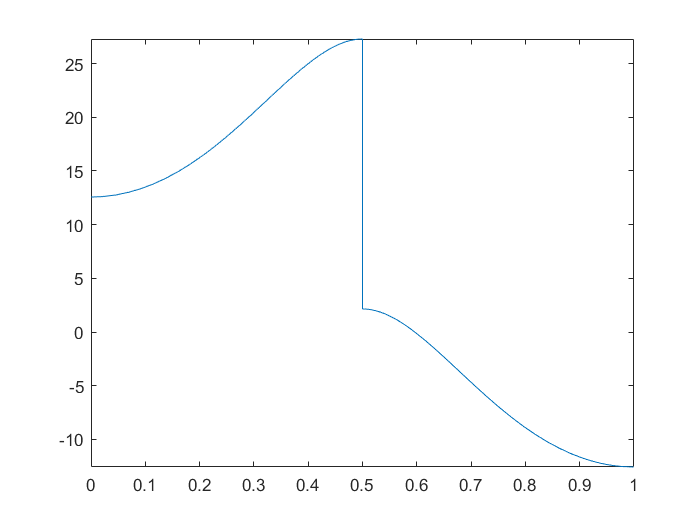


fplot(u1,[0,T_])

figure
% 
% u2=(qa_piece2(1,:))*I_
% fplot(u2,[0,T_])
% figure

## as the max u is suprpassedthen it is needed a re set of total time

U_nom=25

U_nom = 25

k=round(max(1,sqrt((u_max_-g_max_)/(U_nom-g_max_))),4)

$$k = 1.1054$$


T_s_=vpa(k*T_)

$$T\_s\_ = 1.1054$$

A_s_=4*(qB_-qA)/T_s_^2

$$A\_s\_ = 3.2735657698154910304461585344037\,\pi$$

[qa_piece22,Tres_,V_,qa_piece_sym] = BangBangPRofile(qA(1,1),qB_(1,1), A_s_,T_s_)

$$qa\_piece = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ A_{1}\,\left(\frac{T}{2}-t\right)+\frac{A_{1}\,T}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ \frac{A_{1}\,T^{2}}{8}-\frac{A_{1}\,{\left(\frac{T}{2}-t\right)}^{2}}{2}-\frac{A_{1}\,T\,\left(\frac{T}{2}-t\right)}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right. \end{array}\right)$$

$$qa\_piece22 = \left(\begin{array}{c} \left\{ \begin{array}{cl} 10.285 & \text{ if }t\in \left[0.0,0.55267877756488600904784725386475\right)\\ -10.285 & \text{ if }t\in \left[0.55267877756488600904784725386475,1.1053575551297720180956945077295\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 10.285\,t & \text{ if }t\in \left[0.0,0.55267877756488600904784725386475\right)\\ 11.368602454509705206114218011998-10.285\,t & \text{ if }t\in \left[0.55267877756488600904784725386475,1.1053575551297720180956945077295\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 5.1425\,t^{2} & \text{ if }t\in \left[0.0,0.55267877756488600904784725386475\right)\\ 5.6843012272548526030571090059989\,t-5.1425\,{\left(t-0.55267877756488600904784725386475\right)}^{2}-1.5707963267948966192313216916398 & \text{ if }t\in \left[0.55267877756488600904784725386475,1.1053575551297720180956945077295\right) \end{array}\right. \end{array}\right)$$

$$Tres\_ = 1.1053575551297720180956945077295$$

$$V\_ = 1.8093692766818737648060370793656\,\pi$$

$$qa\_piece\_sym = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ A_{1}\,\left(\frac{T}{2}-t\right)+\frac{A_{1}\,T}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ \frac{A_{1}\,T^{2}}{8}-\frac{A_{1}\,{\left(\frac{T}{2}-t\right)}^{2}}{2}-\frac{A_{1}\,T\,\left(\frac{T}{2}-t\right)}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right. \end{array}\right)$$

u12=subs(u_,[z.q;q_ddot],[qa_piece22(3,:);qa_piece22(1,:)])

$$u12 = \left\{ \begin{array}{cl} \frac{2943\,\sin\left(5.1425\,t^{2}\right)}{200}+10.285 & \text{ if }t\in \left[0.0,0.55267877756488600904784725386475\right)\\ -\frac{2943\,\sin\left(5.1425\,{\left(t-0.55267877756488600904784725386475\right)}^{2}-5.6843012272548526030571090059989\,t+1.5707963267948966192313216916398\right)}{200}-10.285 & \text{ if }t\in \left[0.55267877756488600904784725386475,1.1053575551297720180956945077295\right) \end{array}\right.$$

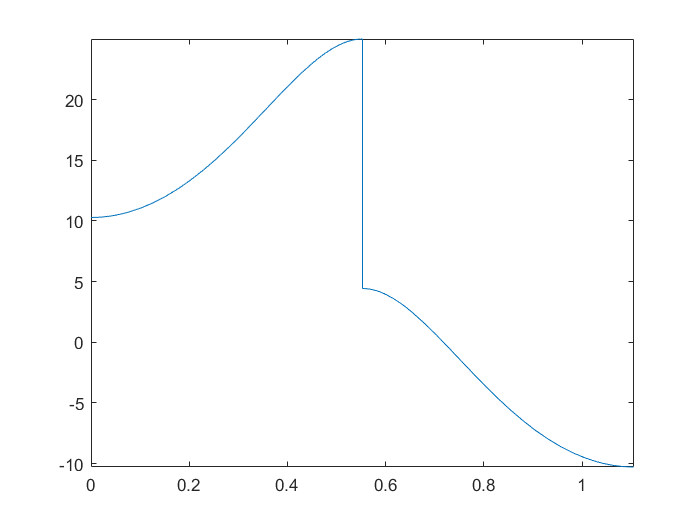


fplot(u12,[0,1.1054])

figure